# fise_imageHarmonics1d

Create the 1D image harmonic examples.

## Initialize the environment

ieInit; % Initialize the Image Engineering environment
fise_plotDefaults; % Set default plotting parameters

## Define grid for harmonics

x = linspace(0, 1, 512); % Create a linearly spaced vector
[X, Y] = meshgrid(x, x); % Create a 2D grid of coordinates

## Generate and display 2D optics harmonics

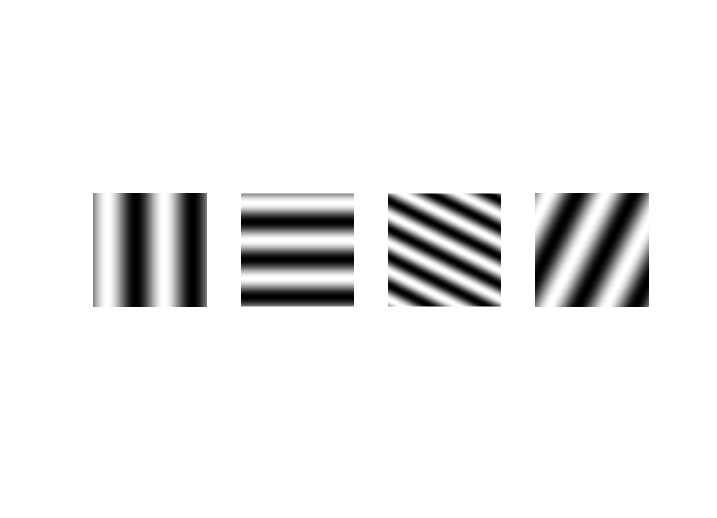

ieFigure; % Create a new figure window
tiledlayout(1,4);
% Define and plot each harmonic image
harmonics = [2, 0; 0, 3; 2, -4; 2, 1]; % Define frequency pairs
for k = 1:size(harmonics, 1)
    nexttile;
    fx = harmonics(k, 1); % Extract frequency in x-direction
    fy = harmonics(k, 2); % Extract frequency in y-direction
    img = 1 + sin(2 * pi * fx * X + 2 * pi * fy * Y); % Calculate harmonic image
    imagesc(x, x, img); % Display the image
    colormap(gray); % Set colormap to grayscale
    axis off image; % Adjust axis properties
    axis tight
end


%{
% Uncomment to save the figure
fname = fullfile(fiseRootPath, 'chapters', 'images', 'optics', 'optics-harmonics.png');
exportgraphics(gcf, fname); 
%}


## Generate and display 1D optics harmonics

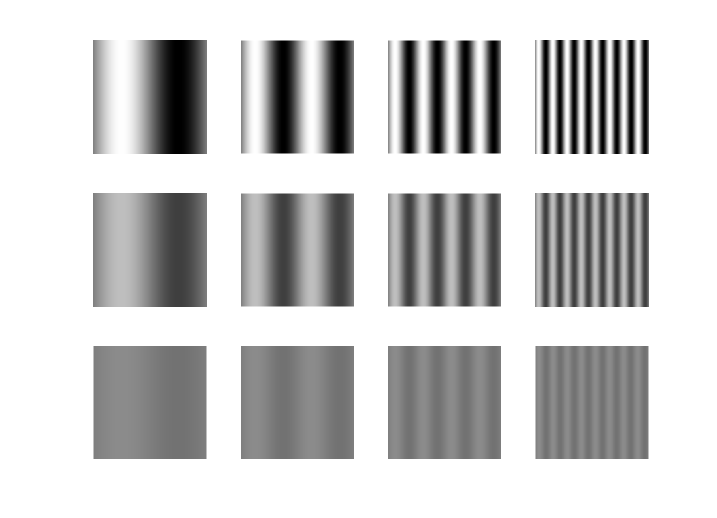

ieFigure; % Create a new figure window
tiledlayout(3, 4); % Set up a tiled layout for 12 plots
fy = 0; % Set fixed frequency in y-direction

% Loop through contrast and frequency values to generate images
contrast_values = [1, 0.5, 0.1]; % Define contrast values
frequency_values = [1, 2, 4, 8]; % Define frequency values
for cx = contrast_values
    for fx = frequency_values
        nexttile; % Move to the next tile
        img = (1 + cx * sin(2 * pi * fx * X + 2 * pi * fy * Y)) * 128; % Calculate harmonic image
        image(x, x, img); % Display the image
        colormap(gray); % Set colormap to grayscale
        axis off image tight; % Adjust axis properties
    end
end


%{
% Uncomment to save the figure
 fname = fullfile(fiseRootPath, 'chapters', 'images', 'optics', 'optics-harmonics-1d.png');
 exportgraphics(gcf, fname); 
%}
